**Question 1**

a. Load and plot the data

% load data
load mdph607_projection_data_v2.mat

% turn intensity values to m values which are linear in mu
data1 = preprocess(dataset1);
data2 = preprocess(dataset2);

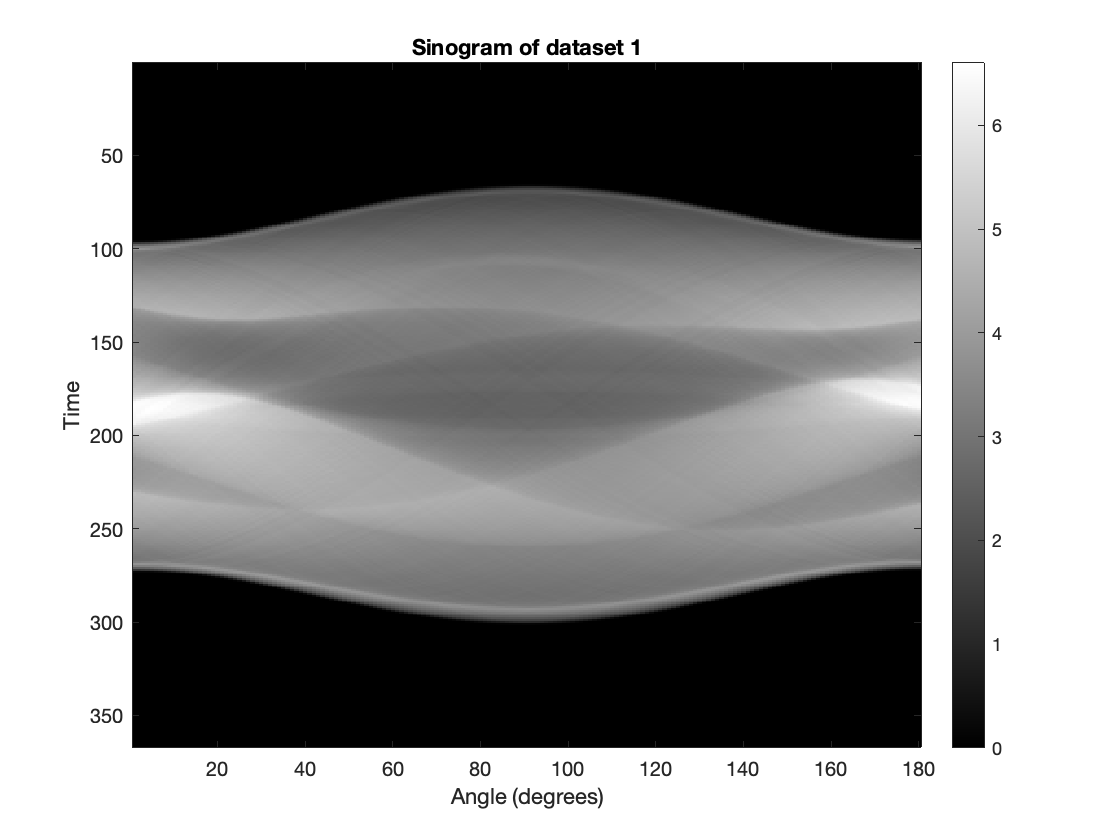

% plot the sinogram of dataset 1
figure;
imagesc(data1)
colorbar; colormap gray
title("Sinogram of dataset 1")
xlabel("Angle (degrees)")
ylabel("Time")

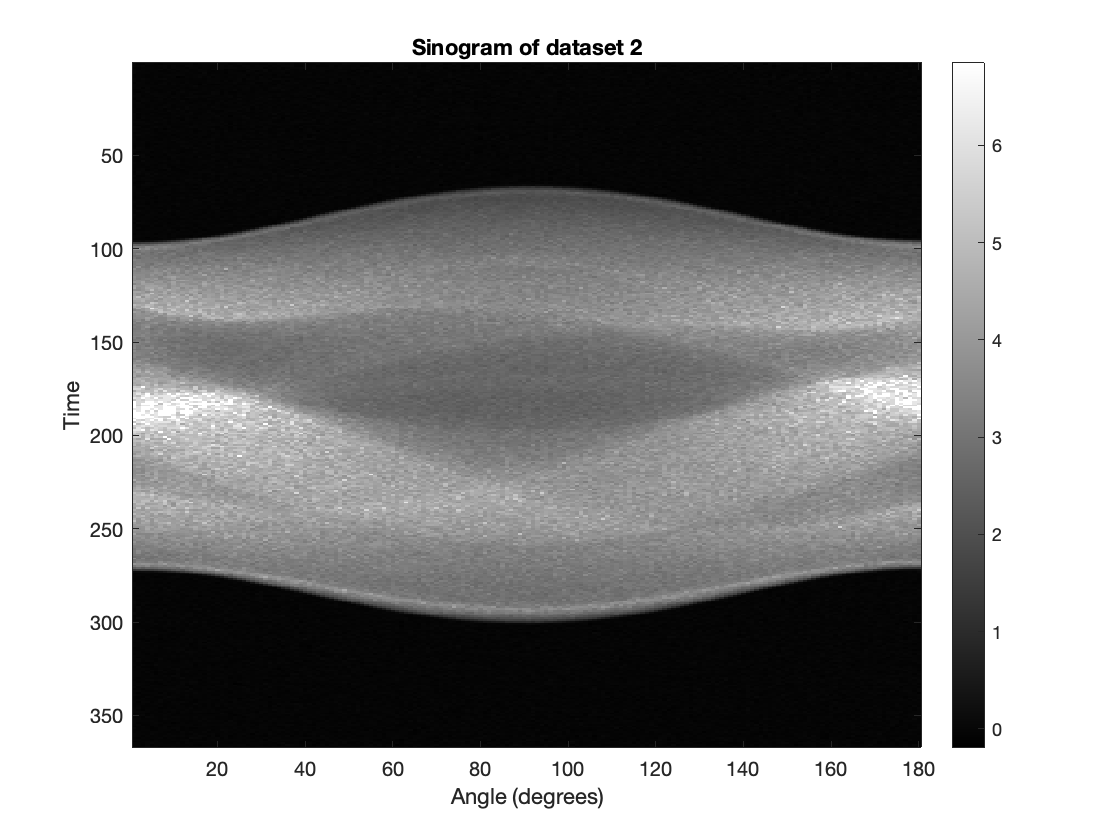

% plot the sinogram of dataset 2
figure;
imagesc(data2)
colorbar; colormap gray
title("Sinogram of dataset 2")
xlabel("Angle (degrees)")
ylabel("Time")

b. Reconstruct dataset 1

% Simple backprojection
im_nofilt_1 = iradon(data1,0:179,'linear','none');

% Filtered backprojection with Ram-Lak window
im_ramp_1 = iradon(data1,0:179,'linear','Ram-Lak');

% Filtered backprojection with Hann window
im_hann_1 = iradon(data1,0:179,'linear','Hann');

% convert to Hounsfield units
im_nofilt_1 = to_HU(im_nofilt_1, mu_water);
im_ramp_1 = to_HU(im_ramp_1, mu_water);
im_hann_1 = to_HU(im_hann_1, mu_water);

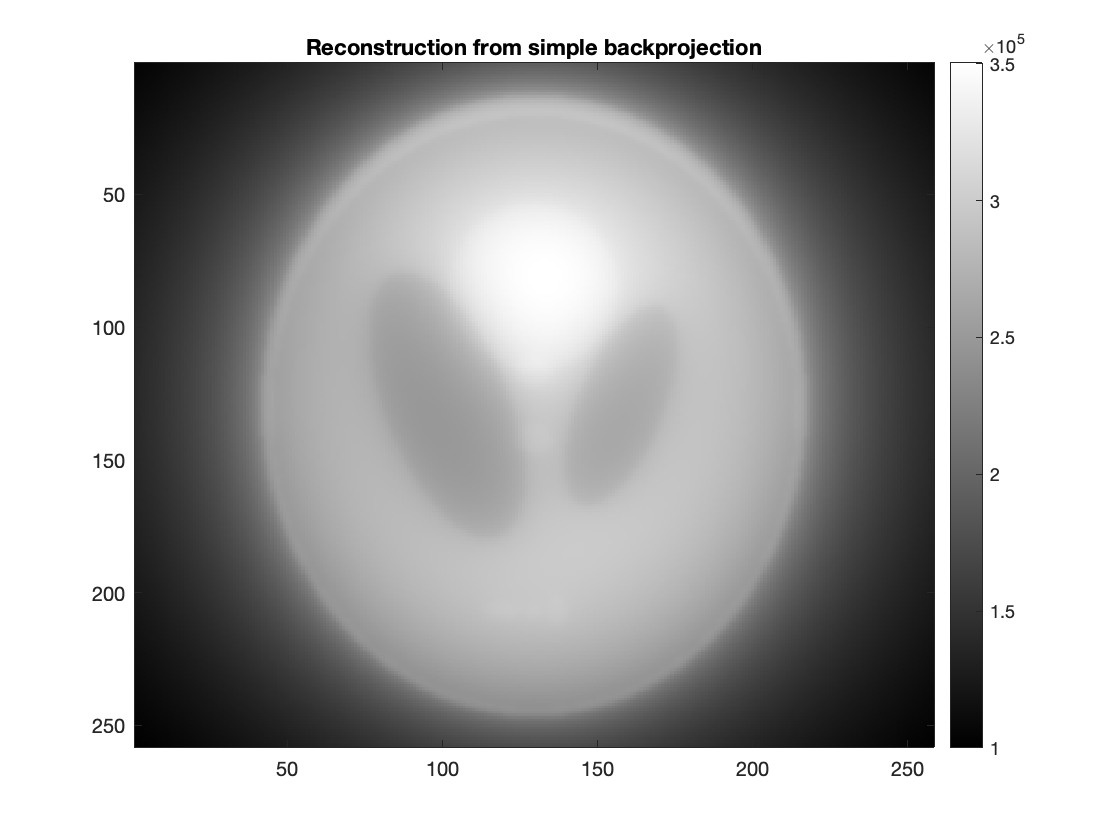

% plots
figure;
imagesc(im_nofilt_1); colorbar
title("Reconstruction from simple backprojection")
colormap gray

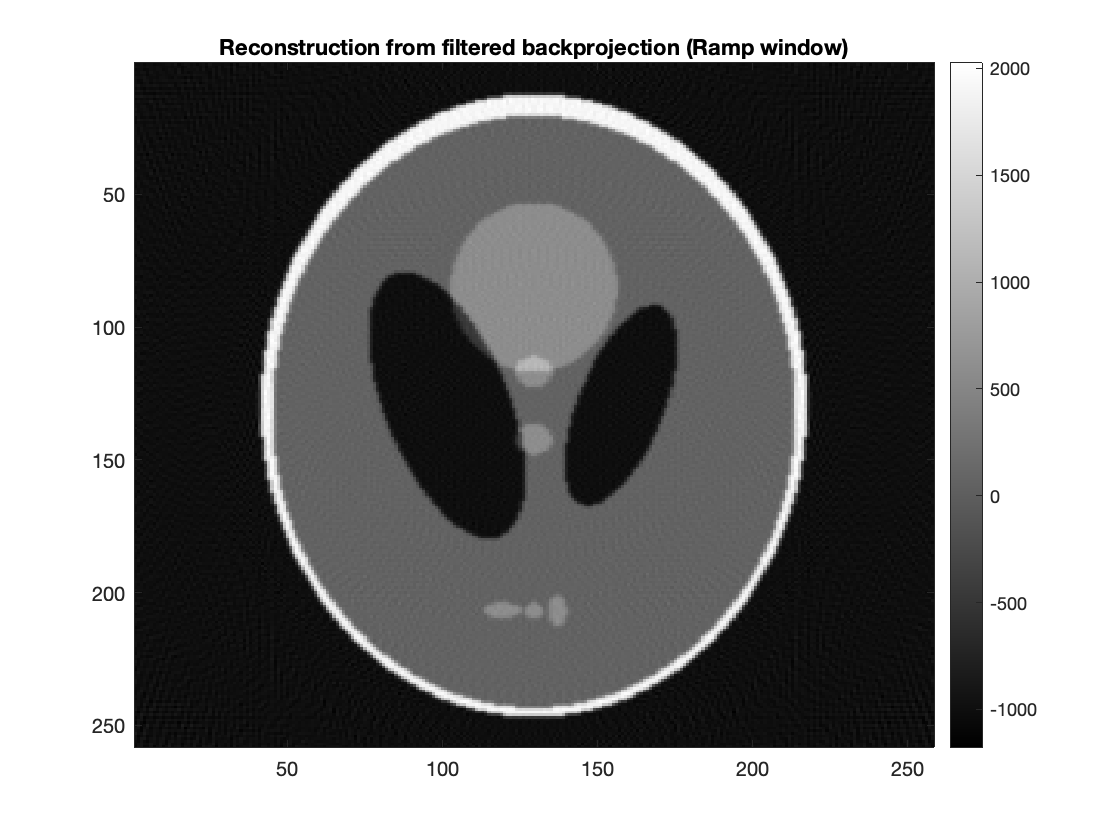


figure;
imagesc(im_ramp_1); colorbar
title("Reconstruction from filtered backprojection (Ramp window)")
colormap gray

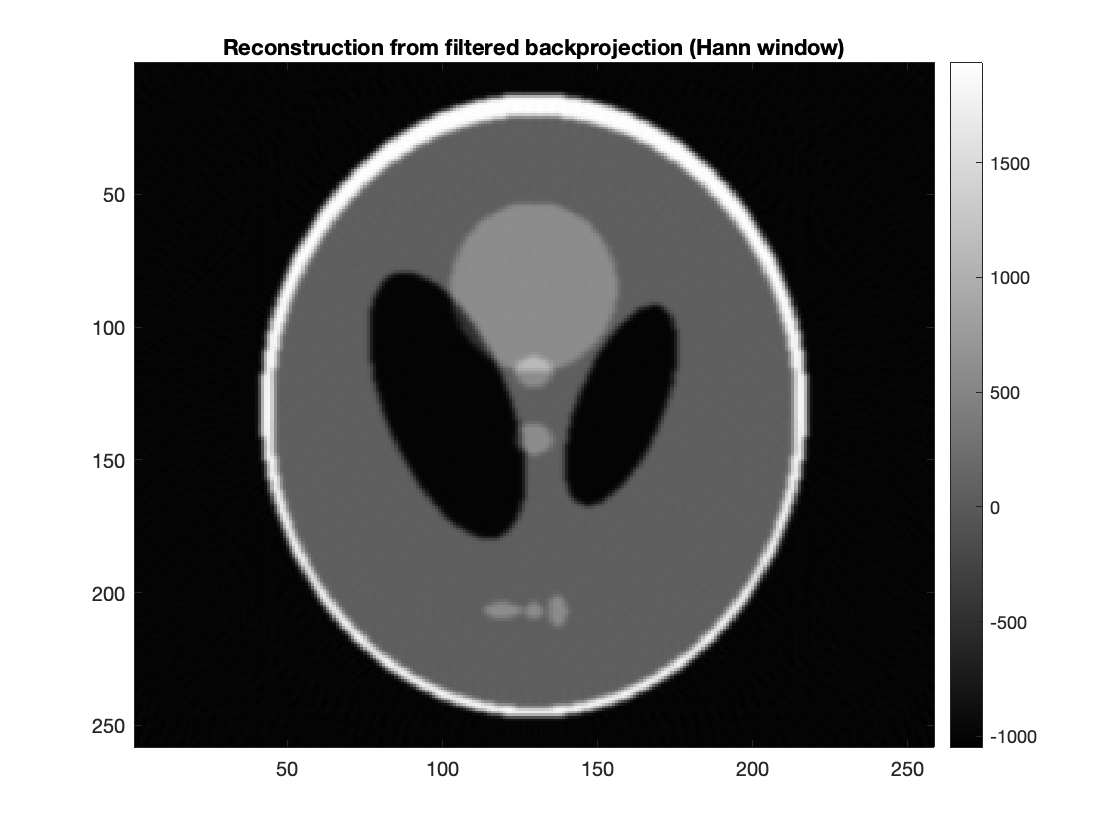


figure;
imagesc(im_hann_1); colorbar
title("Reconstruction from filtered backprojection (Hann window)")
colormap gray

Observations: There does not seem to be a noticeable difference in the image from switching filters. There is a lack of high resolution information in the simple backprojection, though the low-frequency information is roughly apparent.

c. Reduce number of projections by sampling every 3rd column

% sample the sinogram at every 3rd angle
angles = 0:3:179;

% Simple backprojection
im_nofilt_1 = iradon(data1(:,angles+1), angles,'linear','none');

% Filtered backprojection with Ram-Lak window
im_ramp_1 = iradon(data1(:,angles+1),angles,'linear','Ram-Lak');

% Filtered backprojection with Hann window
im_hann_1 = iradon(data1(:,angles+1),angles,'linear','Hann');

% convert to Hounsfield units
im_nofilt_1 = to_HU(im_nofilt_1, mu_water);
im_ramp_1 = to_HU(im_ramp_1, mu_water);
im_hann_1 = to_HU(im_hann_1, mu_water);

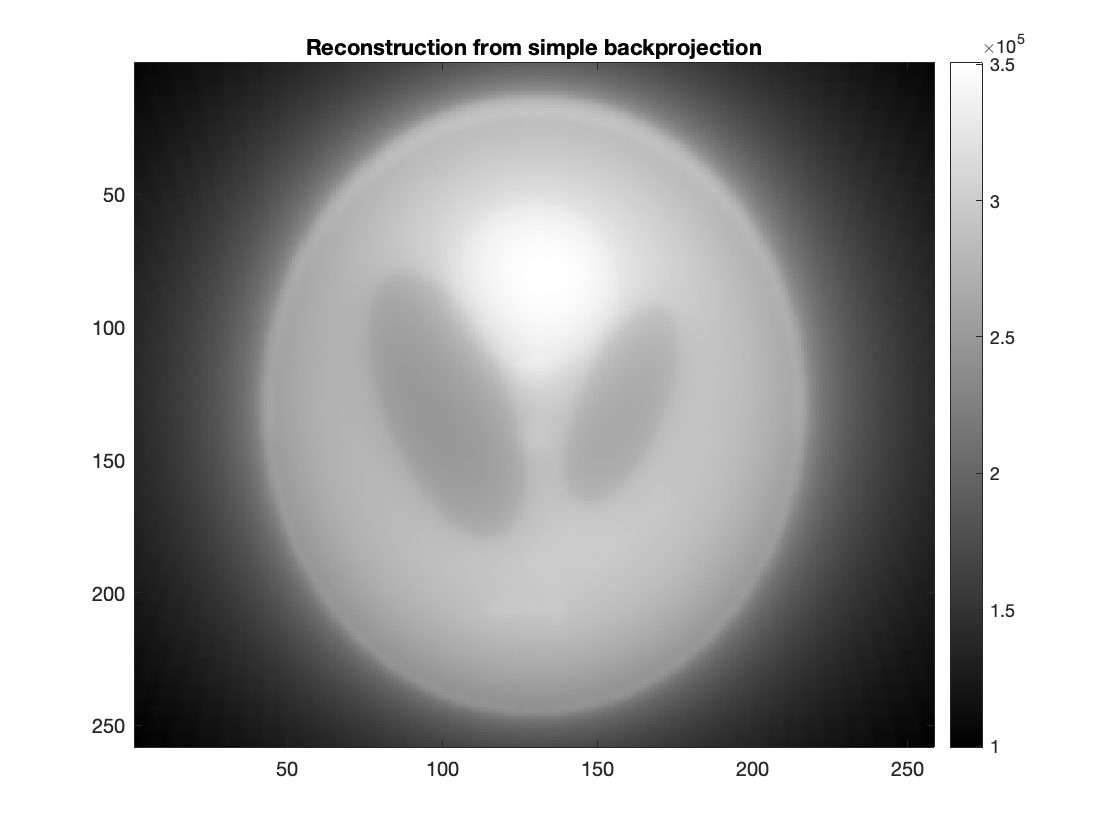

% plots
figure;
imagesc(im_nofilt_1); colorbar
title("Reconstruction from simple backprojection")
colormap gray

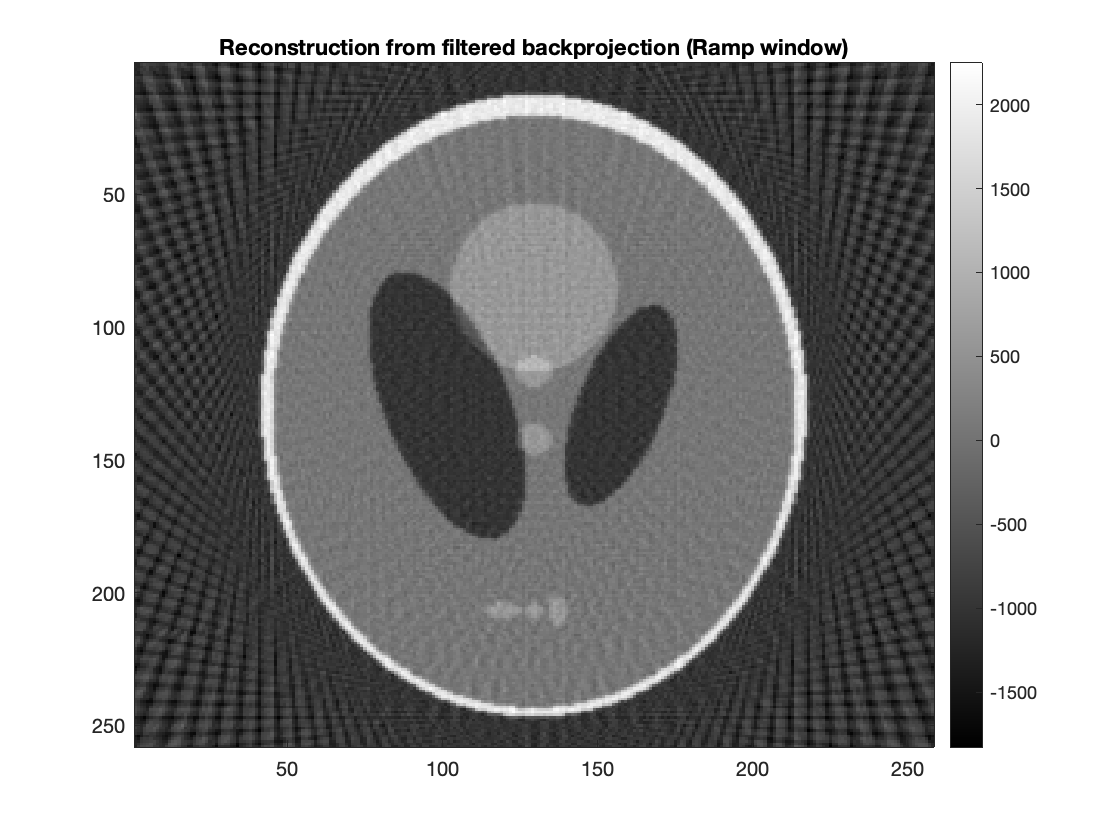


figure;
imagesc(im_ramp_1); colorbar
title("Reconstruction from filtered backprojection (Ramp window)")
colormap gray

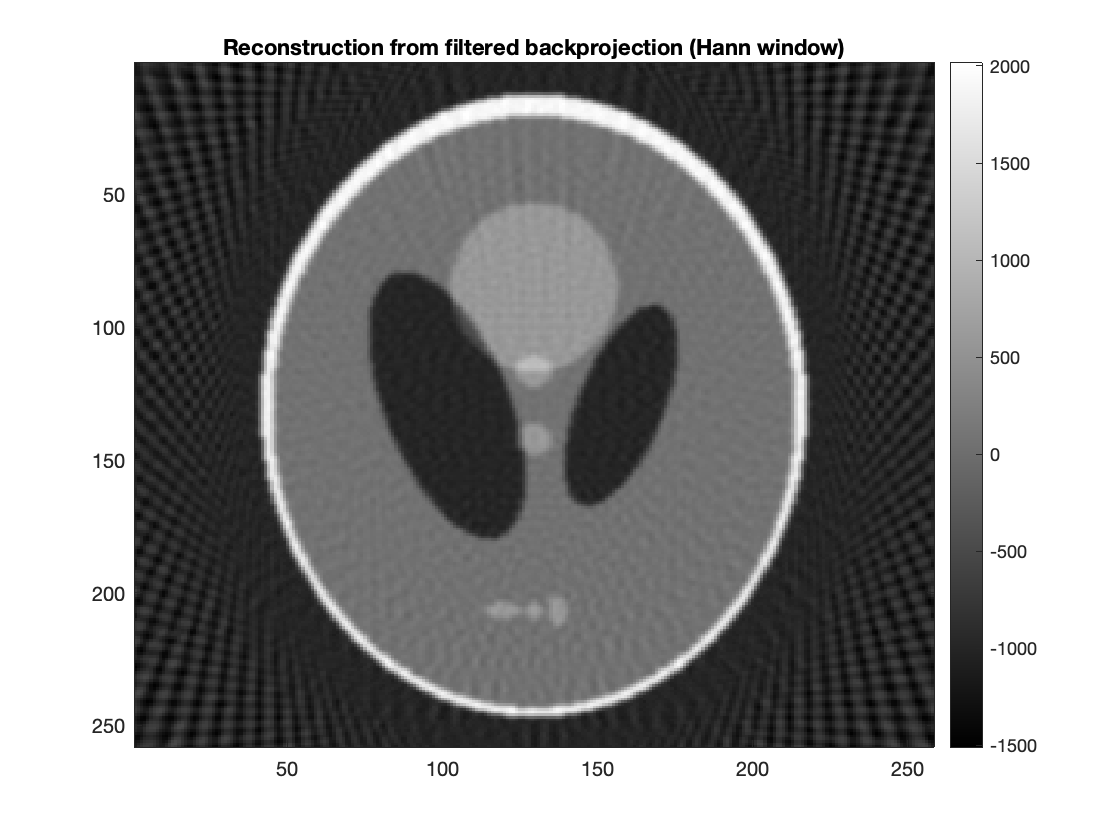


figure;
imagesc(im_hann_1); colorbar
title("Reconstruction from filtered backprojection (Hann window)")
colormap gray

Reducing the number of angles by a factor of 3 increases the noise.

d. Reduce number of projections by keeping only the first 1/3rd columns

% sample the sinogram at every 3rd angle
angles = 0:59;

% Simple backprojection
im_nofilt_1 = iradon(data1(:,angles+1), angles,'linear','none');

% Filtered backprojection with Ram-Lak window
im_ramp_1 = iradon(data1(:,angles+1),angles,'linear','Ram-Lak');

% Filtered backprojection with Hann window
im_hann_1 = iradon(data1(:,angles+1),angles,'linear','Hann');

% convert to Hounsfield units
im_nofilt_1 = to_HU(im_nofilt_1, mu_water);
im_ramp_1 = to_HU(im_ramp_1, mu_water);
im_hann_1 = to_HU(im_hann_1, mu_water);

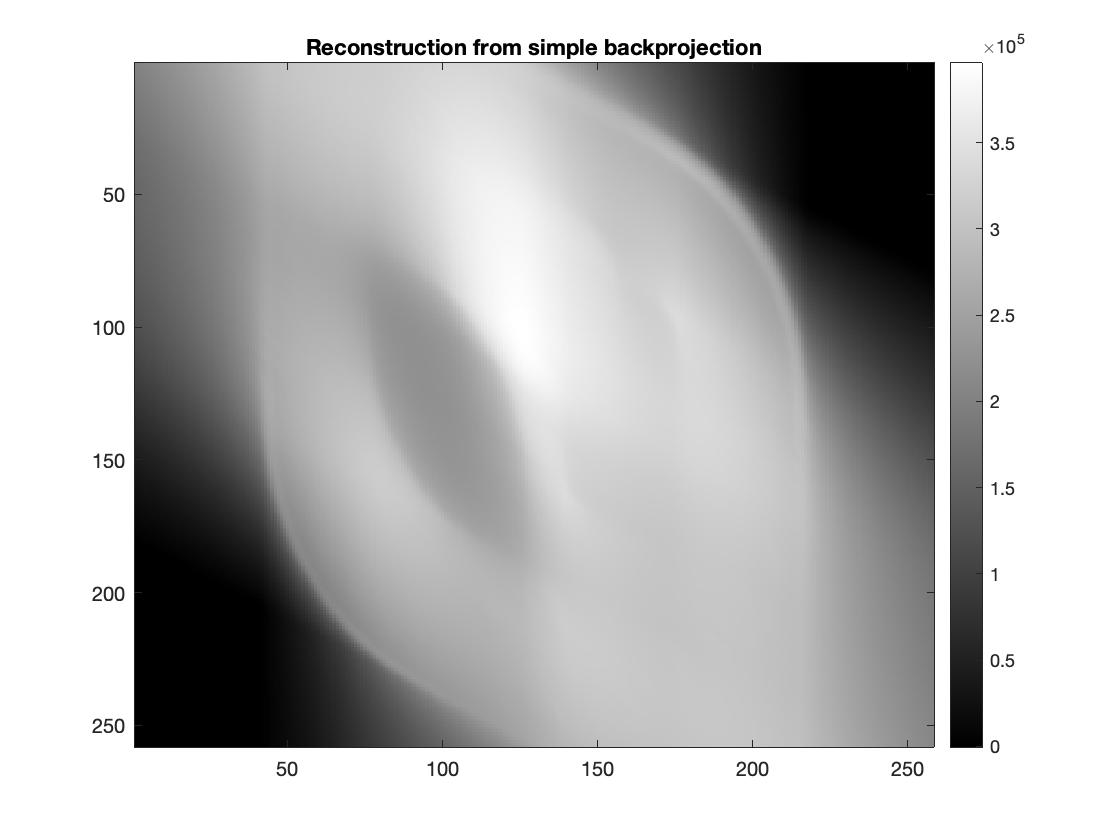

% plots
figure;
imagesc(im_nofilt_1); colorbar
title("Reconstruction from simple backprojection")
colormap gray

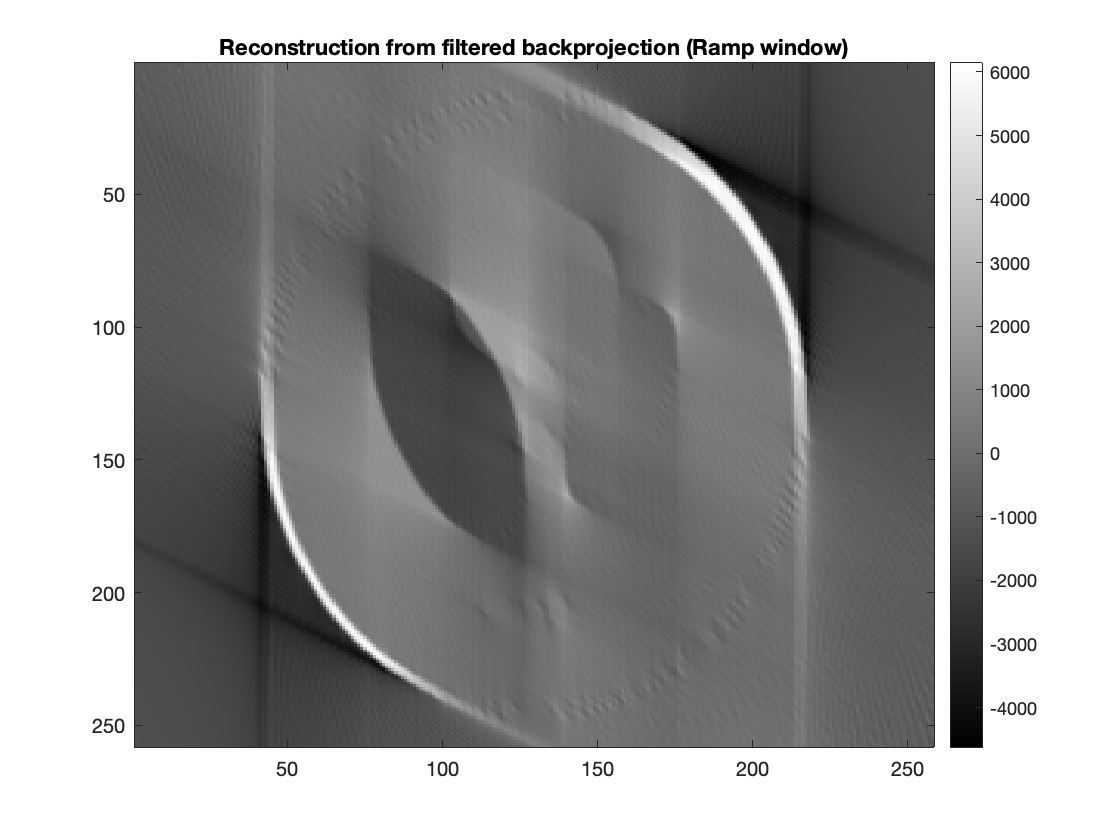


figure;
imagesc(im_ramp_1); colorbar
title("Reconstruction from filtered backprojection (Ramp window)")
colormap gray

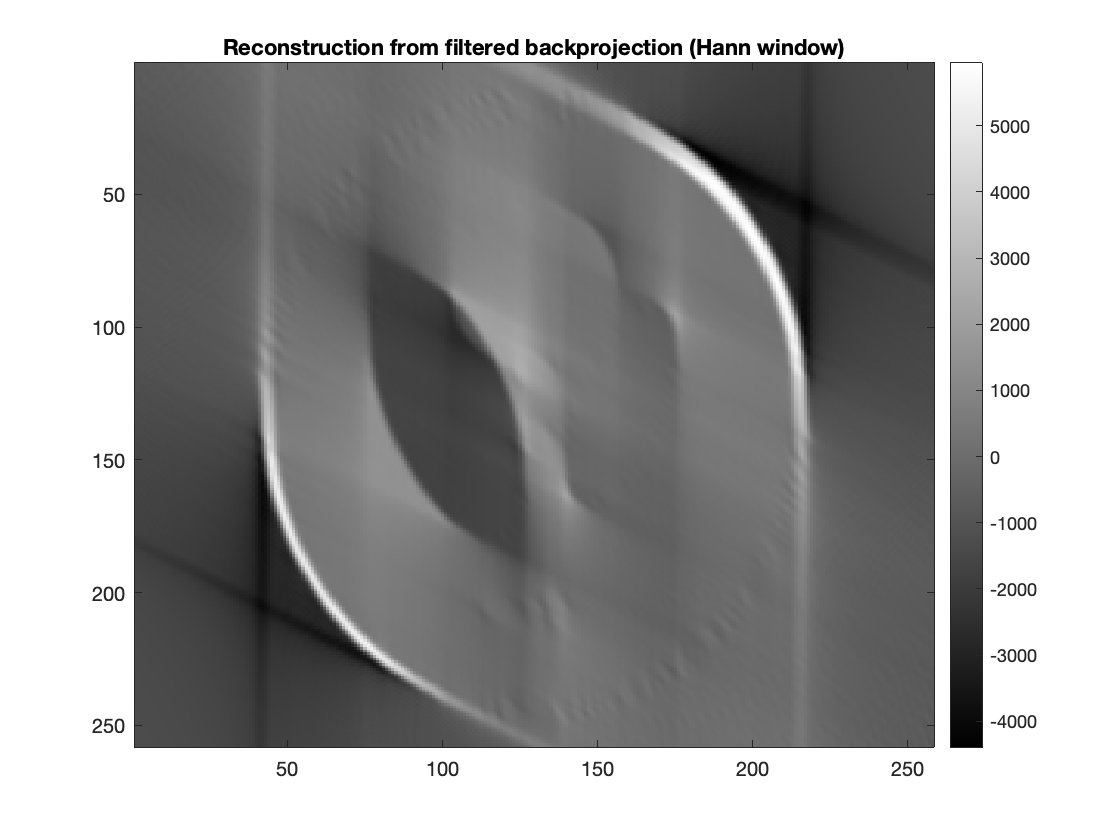


figure;
imagesc(im_hann_1); colorbar
title("Reconstruction from filtered backprojection (Hann window)")
colormap gray

Reducing the angle coverage by keeping the first 3rd of the columns degrades the image significantly — much more than the degredation from sampling every 3rd column. However, we can still see the general outline of the skull for some angles.

e. Results for dataset 2

% Simple backprojection
im_nofilt_2 = iradon(data2,0:179,'linear','none');

% Filtered backprojection with Ram-Lak window
im_ramp_2 = iradon(data2,0:179,'linear','Ram-Lak');

% Filtered backprojection with Hann window
im_hann_2 = iradon(data2,0:179,'linear','Hann');

% convert to Hounsfield units
im_nofilt_2 = to_HU(im_nofilt_2, mu_water);
im_ramp_2 = to_HU(im_ramp_2, mu_water);
im_hann_2 = to_HU(im_hann_2, mu_water);

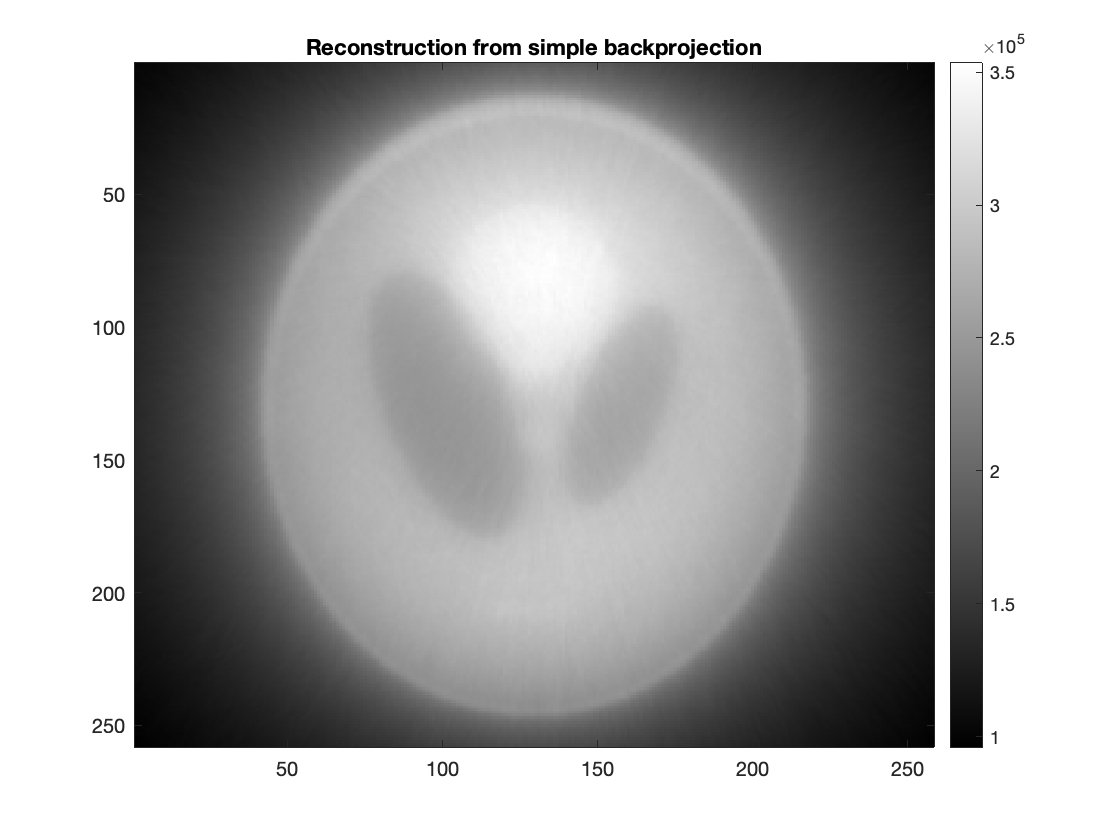

% plots
figure;
imagesc(im_nofilt_2); colorbar
title("Reconstruction from simple backprojection")
colormap gray

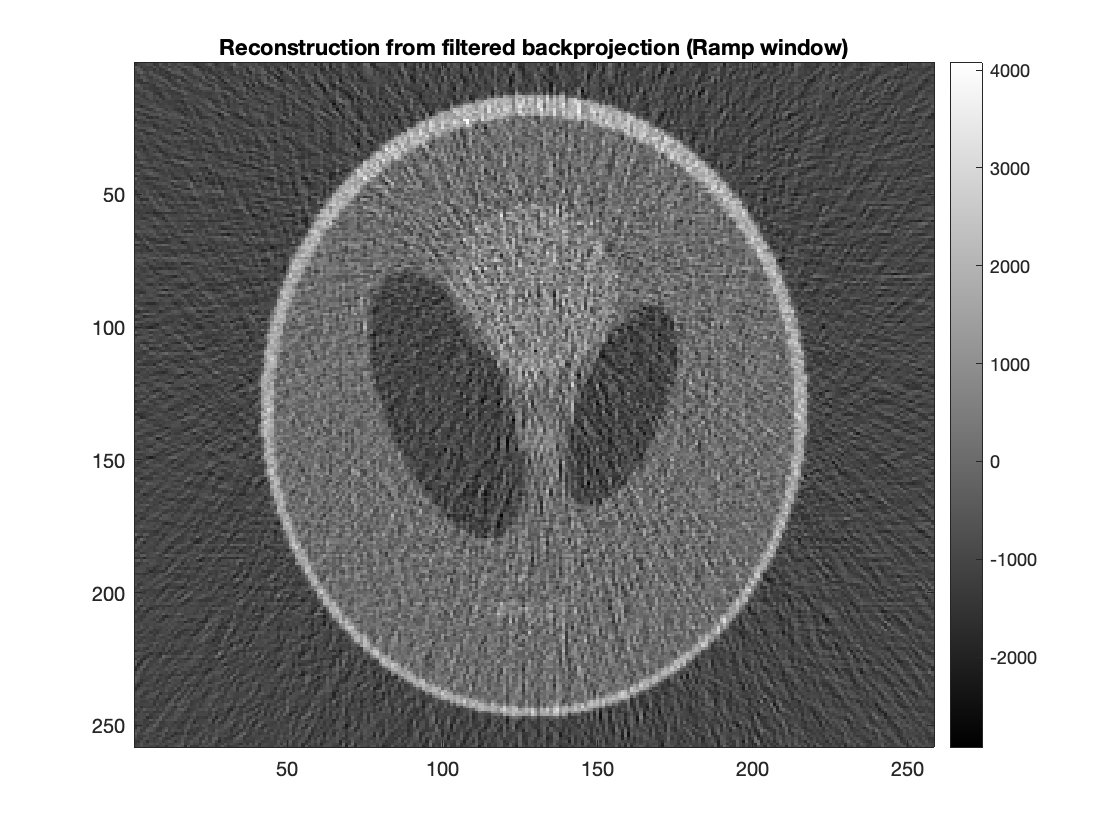


figure;
imagesc(im_ramp_2); colorbar
title("Reconstruction from filtered backprojection (Ramp window)")
colormap gray

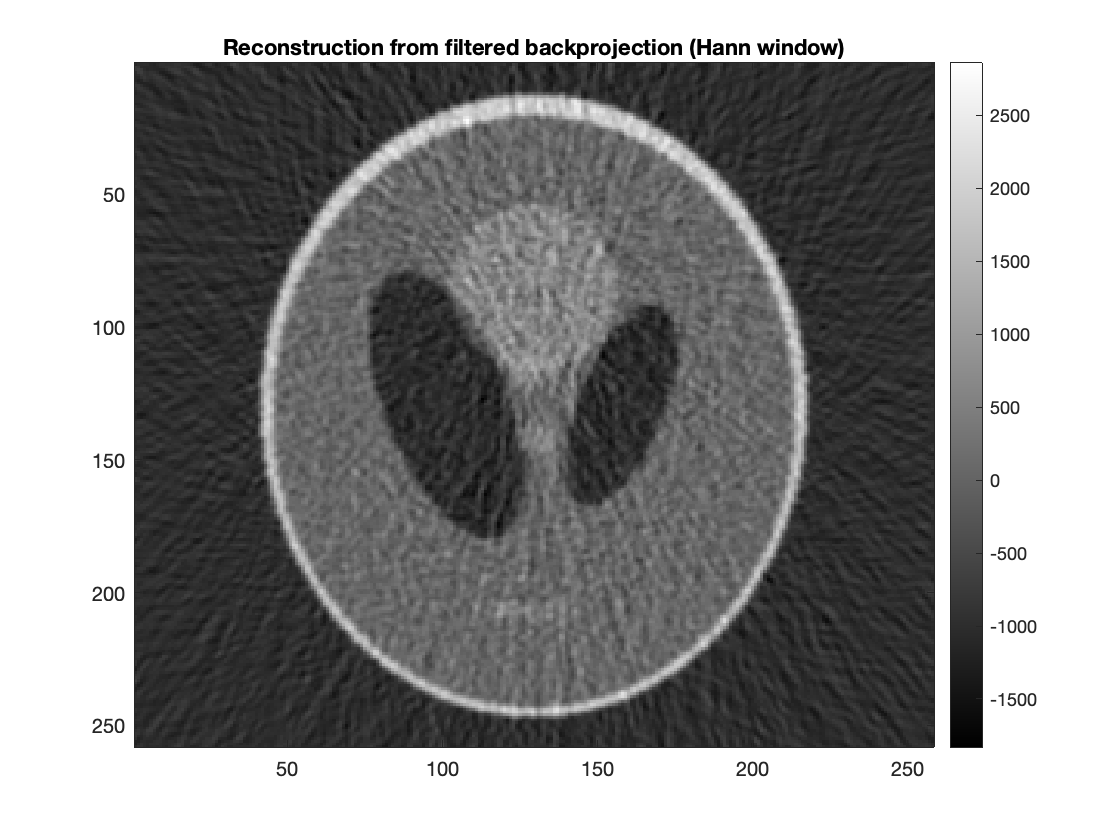


figure;
imagesc(im_hann_2); colorbar
title("Reconstruction from filtered backprojection (Hann window)")
colormap gray

Histograms

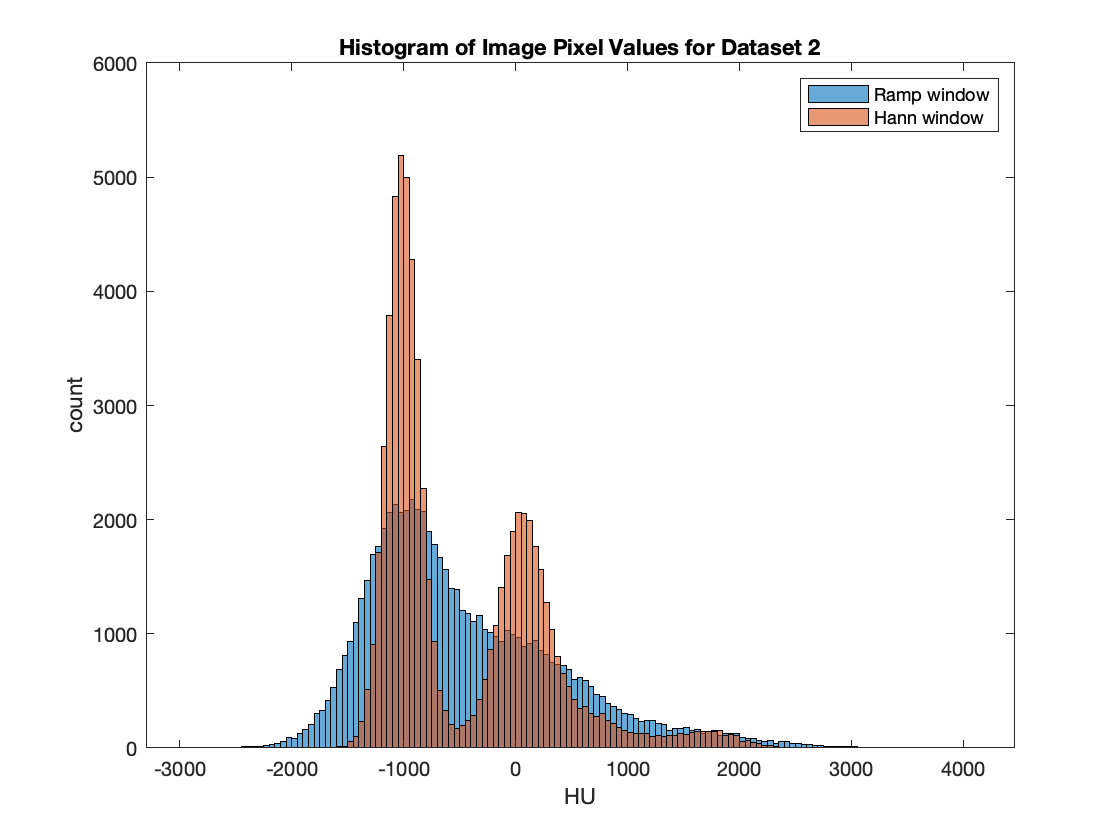

% Plot histograms
histogram(im_ramp_2);
hold on
histogram(im_hann_2);
xlabel("HU")
ylabel("count")
legend('Ramp window', 'Hann window')
title("Histogram of Image Pixel Values for Dataset 2")

Observations: The reconstructed image is noisier. The choice of filter does matter here — the image from the Hann window has better contrast than that from the Ramp window. This makes sense as the Ramp window amplifies the noise in the high frequency range. We can also see this from the histograms — the Hann window can separate the lobes much better, whereas the Ramp window blurs the lobes.